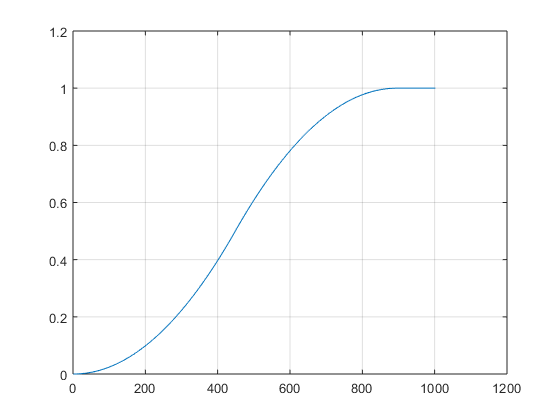

jm = 5;
am = 5;
ts = 0.001;
r = 1; a = 0; v = 0; l = 0;
for t = 0:ts:1
    e = r - v;
%     [j, o] = fhan(-e, a, jm, ts);
%     j = ftoc(-e, a, jm);
    j = fgao(-e, a, jm, ts);
    v = v + a * ts;
    a = a + j * ts;
    a = sat(a, am);
    l = [l v];
end
plot(l); grid;

function y = sat(u, b)
    if abs(u) > b
        y = b * sign(u);
    else
        y = u;
    end
end

function [f, o] = fhan(x1, x2, r, h) 
    d = r * h * h;
    a0 = h * x2;
    y = x1 + a0;
    a1 = sqrt(d * (d + 8 * abs(y)));
    a2 = a0 + sign(y) * (a1 - d) / 2;
    sy = (sign(y + d) - sign(y - d)) / 2;
    a = (a0 + y - a2) * sy + a2;
    sa = (sign(a + d) - sign(a - d)) / 2;
    f = -r * (a / d - sign(a)) * sa - r * sign(a);
    o = x1;
end

function [fst] = fgao(x1, x2, r, h)
    d = r*h;
    d0 = h*d;
    y=x1+h*x2;
    a0=sqrt(d^2+8*r*abs(y));
    if abs(y) > d0
        a = x2 + 0.5*(a0-d)*sign(y);
    else
        a = x2+y/h;
    end
    if abs(a)>d
        fst = -r*sign(a);
    else
        fst = -r*a/d;
    end
end

function [u] = ftoc(x1, x2, r)
    u = -r * sign(x1 + .5 * x2 * abs(x2) / r);
end